clear all
clf
% first manually delete tab References
v1 = 'GeographicUK.xlsx';
v2 = 'Greenland.xlsx';
v3 = 'Spain.xlsx';
v4 = 'Netherlands.xlsx';
v5 = 'Norway.xlsx';
v6 = 'Syria.xlsx';
ukt = 'UK_AAT.xls';
greent = 'Greenland_AAT.xls';
spaint = 'Spain_AAT.xls';
netht = 'Netherlands_AAT.xls';
nort = 'Norway_AAT.xls';
syrt = 'Syria_AAT.xls';


s1 = readtable (v1); % reading data from the specific Data File

s2 = readtable (v2);

s3 = readtable (v3);

s4 = readtable (v4);

s5 = readtable (v5);

s6 = readtable (v6);

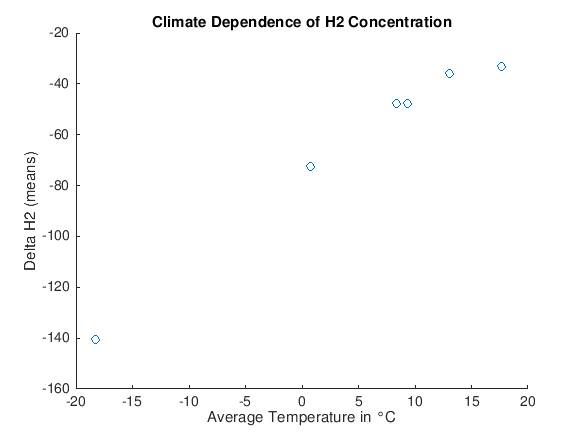

t1 = readtable(ukt);
t2 = readtable(greent);
t3 = readtable(spaint);
t4 = readtable(netht);
t5 = readtable(nort);
t6 = readtable(syrt);

%means and medians of H2, H3, O18 and temperature for different locations
means=[mean(s1.H2,'omitnan'), mean(s1.H3,'omitnan'), mean(s1.O18,'omitnan'), mean(t1.tas,'omitnan')];
medians=[median(s1.H2,'omitnan'), median(s1.H3,'omitnan'), median(s1.O18,'omitnan'), median(t1.tas,'omitnan')];

means=[means;mean(s2.H2,'omitnan'), mean(s2.H3,'omitnan'), mean(s2.O18,'omitnan'), mean(t2.tas,'omitnan')];
medians=[medians;median(s2.H2,'omitnan'), median(s2.H3,'omitnan'), median(s2.O18,'omitnan'), median(t2.tas,'omitnan')];

means=[means;mean(s3.H2,'omitnan'), mean(s3.H3,'omitnan'), mean(s3.O18,'omitnan'), mean(t3.tas,'omitnan')];
medians=[medians;median(s3.H2,'omitnan'), median(s3.H3,'omitnan'), median(s3.O18,'omitnan'), median(t3.tas,'omitnan')];

means=[means;mean(s4.H2,'omitnan'), mean(s4.H3,'omitnan'), mean(s4.O18,'omitnan'), mean(t4.tas,'omitnan')];
medians=[medians;median(s4.H2,'omitnan'), median(s4.H3,'omitnan'), median(s4.O18,'omitnan'), median(t4.tas,'omitnan')];

means=[means;mean(s5.H2,'omitnan'), mean(s5.H3,'omitnan'), mean(s5.O18,'omitnan'), mean(t5.tas,'omitnan')];
medians=[medians;median(s5.H2,'omitnan'), median(s5.H3,'omitnan'), median(s5.O18,'omitnan'), median(t5.tas,'omitnan')];

means=[means;mean(s6.H2,'omitnan'), mean(s6.H3,'omitnan'), mean(s6.O18,'omitnan'), mean(t6.tas,'omitnan')];
medians=[medians;median(s6.H2,'omitnan'), median(s6.H3,'omitnan'), median(s6.O18,'omitnan'), median(t6.tas,'omitnan')];

%Plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     %H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

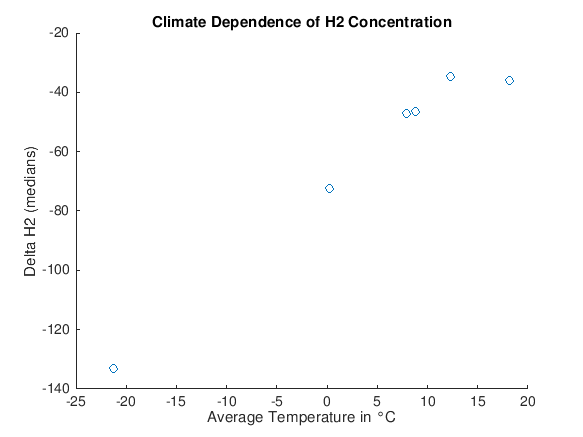


scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

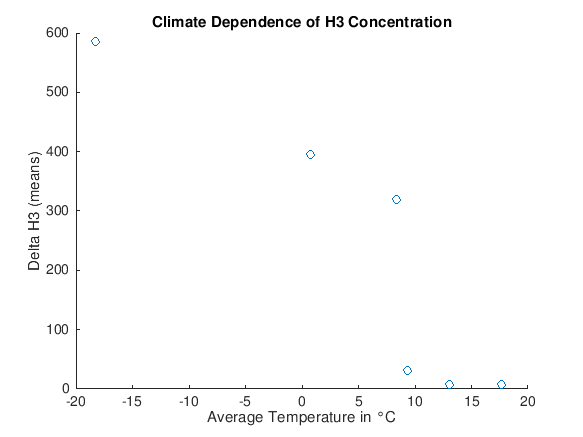


scatter(means(:,4),means(:,2));     %H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

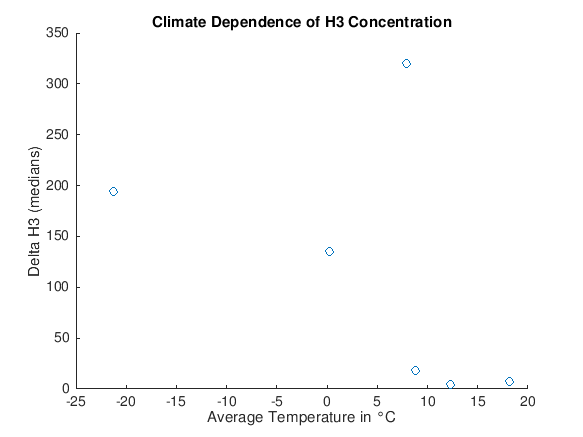


scatter(medians(:,4),medians(:,2));     %H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

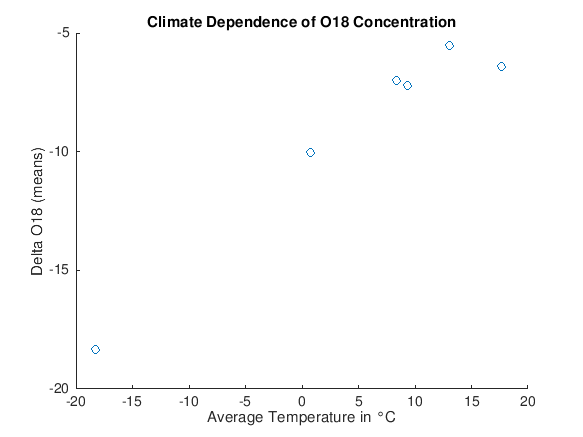


scatter(means(:,4),means(:,3));     %O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

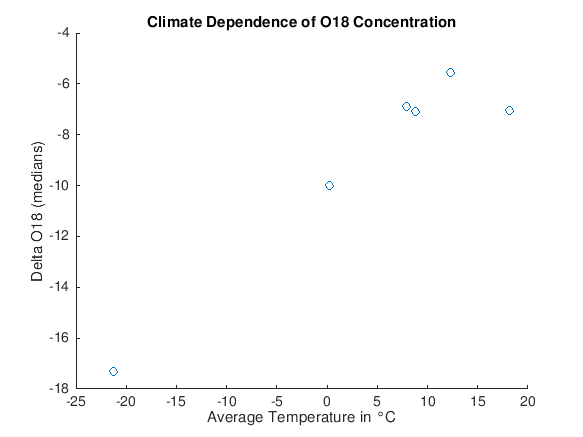


scatter(medians(:,4),medians(:,3));     %O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');